# Acrobot Simulations

Simulate a single acrobot, where the acrobot parameters are as close as possible to the ones of the experiment.

Take the parameters as follows:

- $m$ for the nominal energy is the average of $[ml, mt]$

- $l$ for the nominal energy is the average of $[lt,dt,ll,dl]$

- $\bar{q}_a = 1$ so that $q_a = \arctan(I p_u) \in [-\frac{\pi}{2},\frac{\pi}{2}]$

To choose our control parameter, notice that $E_\pi$ intersects the $p_u$-axis at $p_u = \sqrt{60m^2gl^3}$. Suppose we want to achieve a max actuator angle of $q_a^\text{rot}$ at this intersection point; then the associated control value becomes $I = \tan(q_a^\text{rot})/\sqrt{60m^2gl^3}$.

If we choose $q_a^\text{rot}$ to be $\frac{\pi}{3}$, we get $I = 9.28$. We round this up to $I = 10$ and use this as our control value.

% Choose which simulations to run and which figures to save.
% Note that if RUN is false, figures will not be saved either.
%%% Energy injection
sims.in.RUN = false;
sims.in.SAVE = false; % save injection figures
%%% Monte carlo for energy injection
sims.mc_in.RUN = false;
sims.mc_in.SAVE = false; % save mc figures
%%% Energy Dissipation
sims.diss.RUN = false;
sims.diss.SAVE = false; % save dissipation figures
%%% Oscillation Regulation
sims.osc_reg.RUN = true;
sims.osc_reg.qp0s = [pi/32, 0    ; ...
                         0, 0.19]; % initial conditions (rows)
sims.osc_reg.SAVE = true; % save oscillation regulation figs
%%% Rotation Regulation
sims.rot_reg.RUN = true;
sims.rot_reg.qp0s = [pi/2, 0    ; ...
                         0, 0.23]; % initial conditions (rows)
sims.rot_reg.SAVE = true; % save oscillation regulation figs
%%% Energy Regulation
sims.energy_reg.RUN = false;
sims.energy_reg.SAVE = false; % save regulation figures

% Setup the real acrobot's parameters
mt = 0.2112;  ml = 0.1979; % masses, kg
lt = 0.073;   ll = 0.083; % com, m
dt = 0.148;   dl = 0.145; % length of limbs, m
Jt = 0.00129; Jl = 0.00075; % moment of inertia
g = 9.81; % gravity, m/s^2

% Set up the symbolic variables for the real acrobot
qu = sym('qu','real'); % unactuated shoulder angle
qa = sym('qa','real'); % actuated leg angle
pu = sym('pu','real'); % unactuated momentum
pa = sym('pa','real'); % actuated momentum
I  = sym('I' ,'real'); % control value
c  = sym('c' ,'real'); % constant for VNHC qa = c
assumeAlso(-pi < qu);
assumeAlso(qu <= pi);
assumeAlso(-pi < qa);
assumeAlso(qa <= pi);

% Set the control parameters
qb = 1; % qbar, in [0,1]
Iin = 10;
Idiss = -10;
% Set the VNHC
qaa = qb*atan(I*pu);
qaf = matlabFunction(qaa,'vars',[I,pu]);

% Set up the dynamics
% Mass/Inertia matrix
M = [ml*dt^2+2*ml*cos(qa)*dt*ll+ml*ll^2+mt*lt^2 + Jl+Jt,...
                       ml*ll^2 + ml*dt*ll*cos(qa) + Jl; ...
        ml*ll^2 + ml*dt*ll*cos(qa) + Jl,   ml*ll^2 + Jl];

% Potential function
V = g*(ml*ll*(1 - cos(qu + qa)) + ...
    (ml*dt + mt*lt)*(1 - cos(qu)));
GquV = diff(V,qu);

% Energy
E = 1/2*[pu pa]*(M\[pu;pa]) + V;

% Define the VNHC and the actual pa
h = qa - qaa;
dhq = [diff(h,qu) diff(h,qa)];
dhp = diff(h,pu);
paa = (dhq*(M\[0;1])) \ (dhp*GquV-dhq*(M\[1;0])*pu);
paa = subs(paa,qa,qaa);

% Dynamics
qud = subs(diff(E,pu),[qa pa],[qaa paa]);
pud = -subs(diff(E,qu),[qa pa],[qaa paa]);
qpd = [qud; pud];
qpdf = matlabFunction(qpd,'vars',[qu pu I]);

% Convert it into a form that ode45 can use
fxin = @(t,x)qpdf(wrapToPi(x(1)),x(2),Iin);
fxdiss = @(t,x)qpdf(wrapToPi(x(1)),x(2),Idiss);

% Define the constant VNHC at qa = c
hconst = qa - c;
dhqconst = [diff(hconst,qu) diff(hconst,qa)];
dhpconst = diff(hconst,pu);
paconst = (dhqconst*(M\[0;1])) \...
         (dhpconst*GquV-dhqconst*(M\[1;0])*pu);
paconst = subs(paconst,qa,c);


%%% There's something wrong here.
% qudc does NOT have the hamiltonian E(qu,pu,c,paconst)
% Instead, if you evaluate E(qu,pu,c,paconst) and take its
% dynamics, you don't get the same results as substituting
% qa = c and pa = paconst into qu.
% Strangely, the dynamics for pu are the same in both cases.
% LOOK INTO THIS because it's also giving strange results
% if you use qpdf above (where I = 0 does not match up with
% the dynamics for qa = 0).

% Get the dynamics for the constant VNHC qa = c
qudconst = subs(diff(E,pu),[qa pa],[c paconst]);
pudconst = -subs(diff(E,qu),[qa pa],[c paconst]);
qpdconst = [qudconst; pudconst];
qpdfconst = matlabFunction(qpdconst,'vars',[qu pu c]);
fxconst = @(t,x,c)qpdfconst(wrapToPi(x(1)),x(2),c);

% Define the energy function for qa = c
Econst = subs(E,[qa pa],[c paconst]);
Econstf = matlabFunction(Econst,'vars',[qu, pu c]);

% Define the nominal energy function at qa = 0
Enomf = @(qu,pu) Econstf(qu,pu,0);

% Define the event for the ODE solver
E_in_event = @(t,qp)energyInEvent(t,qp,Enomf,Enomf(pi,0));
E_diss_event = @(t,qp)energyDissEvent(t,qp,Enomf,Enomf(pi,0));
baseInOptions = odeset('RelTol',10e-14,...
                     'AbsTol',10e-14,...
                     'Events',E_in_event);
baseDissOptions = odeset(baseInOptions,...
                     'Events',E_diss_event);
% Simulation time
T = 30;

## Part 1: Energy Injection

Initialize the acrobot at $q_u = \frac{\pi}{32}$ and show the orbit, tracking how long it takes the acrobot to remain outside of $E_\pi$. Also plot the nominal energy $E$.

if sims.in.RUN
% Initial condition
qp0 = [pi/32;0];

% Simulate with an events trigger for when E = E_pi
sol = ode45(fxin,[0,T],qp0,baseInOptions);
% Wrap the qu values to the circle
sol.y(1,:) = wrapToPi(sol.y(1,:));
sol.ye(1,:) = wrapToPi(sol.ye(1,:));

% Plot the nominal E_pi
% First, we compute E_pi itself
Epi = Enomf(pi,0);
% Then we compute the value of E(0,1) to get the
% term in front of pu^2
E01 = Enomf(0,1);
% Finally, we know that E(pi,0)/2 gives us the term in
% front of (1-cos(qu)), so we can get that
% pu^2 = (E(pi,0) - E(pi,0)/2*(1-cos(qu))/E01
qs = linspace(-pi,pi,1000);
ps = sqrt(Epi/2*(2 - (1-cos(qs)))/E01);
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k');
% Now plot the orbit, with scatter point size 0.5 and a 
% light blue colour so it looks nice
scatter(sol.y(1,:),sol.y(2,:),0.5,[0,0.447,0.7410]);
% Show the last time it exits the orbit in red, and every
% other time in black
scatter(sol.ye(1,:),sol.ye(2,:),'k*');
scatter(sol.ye(1,end),sol.ye(2,end),'r*');
% Give it axis labels
xlabel('q_u');
ylabel('p_u');
grid on;
xlim([-pi,pi]);
ylim([-0.2,0.2]);
hold off;
if sims.in.SAVE
saveas(orbitFig,'images/acrobot_in_orbit','png');
saveas(orbitFig,'images/acrobot_in_orbit','fig');
end % SAVE
end % RUN

## Part 1b: Monte-Carlo Simulation

Take as a metric the energy of the nominal pendulum. Randomly initialize the acrobot inside $E(\delta,0)$ for some $\delta > 0$, and measure how long it takes for the acrobot to begin rotating.

if sims.mc_in.RUN
% Initialize the random number generator
rng('shuffle');

% Change the events function to measure how long it
% takes the acrobot to reach a rotation at qu = pi.
mcOptions = odeset(baseInOptions,'Events',@rotationEvent);

% Set the number of trials for the monte carlo method
N = 1000;

% Set the sublevel set as the energy level delta,
% where it is of the form E(delta,0)
delta = pi/32;

% Now initialize N points inside that energy sublevel set
% by taking a random value qu \in [-q0max,q0max] ...
q0s = -delta + 2*delta*rand(1,N);
% ... and find the value p(q0) which satisfies
% E(delta,0) = E(q0,p(q0)), which is the same as
% p(q0)^2 = E(pi,0)/(2*E(0,1)) * (cos(q0) - cos(delta))
pq = sqrt(Epi/2*(cos(q0s) - cos(delta))/E01);
% To set our initial conditions, choose a random pu value
% in [-p(q0), p(q0)].
p0s = -pq + 2*pq.*rand(1,N);
x0s = [q0s;p0s];

% Vector to store how long it takes to rotate
tRot = zeros(1,N);

% Set a progress bar for our simulation
bar = waitbar(0,'Please Wait...');
% Now simulate with the monte carlo method
for i = 1:N
    % Update the waitbar
    waitbar(i/N,bar,...
        sprintf('Running Monte-Carlo Sim %d/%d.',i,N));
    % Get the initial condition
    x0 = x0s(:,i);
    % Simulate using ode45
    soli = ode45(fxin,[0,T],x0,baseInOptions);

    % If the hitting time is empty, repeat this 
    % simulation with a longer time
    % First, set a variable to store the additional time
    Tadd = 0;
    while isempty(soli.xe)
        % Add 5 seconds to the "time to add" variable
        Tadd = Tadd + 5;
        % Update the progress bar to inform the user
        % that we are in this while-loop
        waitbar(i/N,bar,...
          sprintf('Repeating MC %d/%d, adding %d seconds.',...
                  i, N, Tadd));
        % Repeat the simulation
        soli = ode45(fxin,[0,T+Tadd],x0,baseInOptions);
    end
    %
     % Extract how long it took to rotate
    tRot(i) = soli.xe(1);
end
close(bar);

% Save all our data for the monte-carlo sims
mcData.delta = delta;
mcData.x0s = x0s;
mcData.tRot = tRot;

today = datetime;
fname = sprintf('data/acrobot_mc_%d_%d_%d',...
    day(today),...
    month(today),...
    year(today));
save(fname,'mcData');
end % RUN

% Get the average of the first and last hitting times
%tRotAvg = mean(mcData.tRot);
if sims.mc_in.RUN
% Plot first/last hitting time as a function of energy
% E(q0,p0)
mcFig = figure;
hold on;
scatter(Enomf(q0s,p0s),tRot,'b');
% Show the average times
axis([0 max(Enomf(q0s,p0s)) 0 max(tRot)])
ax = axis;
%plot(ax(1:2),[tRotAvg,tRotAvg],'k--');
title('Time to Rotation vs Initial Energy');
xlabel('E(q,p)');
ylabel('t (s)');
hold off;
if sims.mc_in.SAVE
saveas(mcFig,'images/acrobot_mc','png');
saveas(mcFig,'images/acrobot_mc','fig');
end % SAVE
end % RUN

## Part 2: Energy Dissipation

Initialize the acrobot at $(q_u,p_u) = (0,0.18)$ and dissipate using $I = 10$

if sims.diss.RUN
% Initial condition
qp0 = [0;0.19];

% Simulate with an events trigger for when E = E_pi
sol = ode45(fxdiss,[0,T],qp0,baseDissOptions);
% Wrap the qu values to the circle
sol.y(1,:) = wrapToPi(sol.y(1,:));
sol.ye(1,:) = wrapToPi(sol.ye(1,:));

% Plot the nominal E_pi
% First, we compute E_pi itself
Epi = Enomf(pi,0);
% Then we compute the value of E(0,1) to get the
% term in front of pu^2
E01 = Enomf(0,1);
% Finally, we know that E(pi,0)/2 gives us the term in
% front of (1-cos(qu)), so we can get that
% pu^2 = (E(pi,0) - E(pi,0)/2*(1-cos(qu))/E01
qs = linspace(-pi,pi,1000);
ps = sqrt(Epi/2*(2 - (1-cos(qs)))/E01);
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k');
% Now plot the orbit, with scatter point size 0.5 and a 
% light blue colour so it looks nice
scatter(sol.y(1,:),sol.y(2,:),0.5,[0,0.447,0.7410]);
% Show the last time it enters the Epi orbit in red, and every
% other time in black
scatter(sol.ye(1,:),sol.ye(2,:),'k*');
scatter(sol.ye(1,end),sol.ye(2,end),'r*');
% Give it axis labels
xlabel('q_u');
ylabel('p_u');
grid on;
xlim([-pi,pi]);
ylim([-0.2,0.2]);
hold off;
if sims.diss.SAVE
saveas(orbitFig,'images/acrobot_diss_orbit','png');
saveas(orbitFig,'images/acrobot_diss_orbit','fig');
end % SAVE
end % RUN

## Part 3: Oscillation Regulation

We regulate oscillations using a simple supervisor which toggles between injection and dissipation VNHCs.

Given a desired oscillation $q_d \in [0,\pi[$ and a hysteresis $\delta \in [0,1]$, we will switch between injection and dissipation at each crossing of the $q_u$-axis. If at time $t_k$ we cross the $q_u$-axis at the point $q_u(t_k) < (1-\delta)q_d$ then we use the injection VNHC. If $q(t_k) > (1+\delta)q_d$, then we use the dissipation VNHC. If we cross at $(1-\delta)q_d \leq q(t_k) \leq (1+\delta)q_d$, then we keep the value of $q_a$ constant.

Note that if we ever hit the phase with $q_u = \pm \pi$ we have entered a rotation and should immediately switch to the dissipation VNHC.

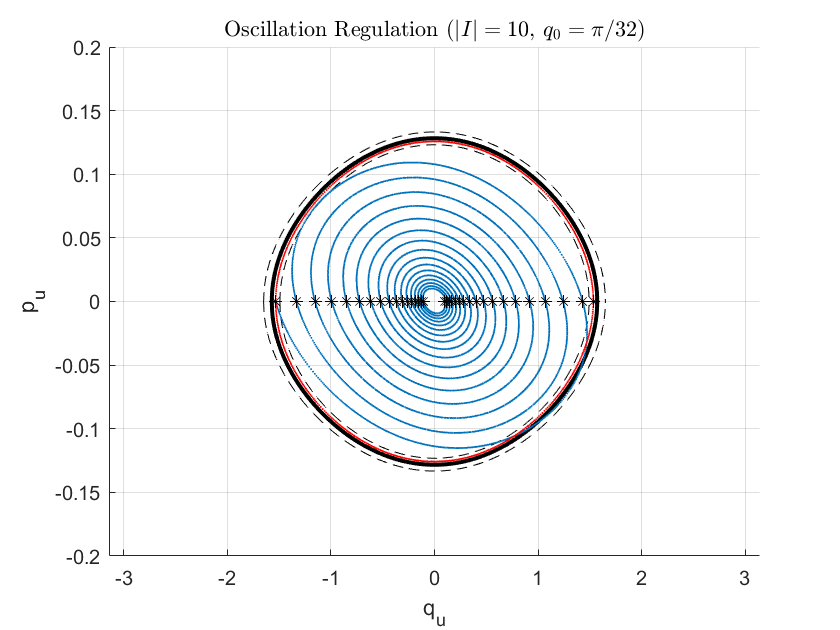

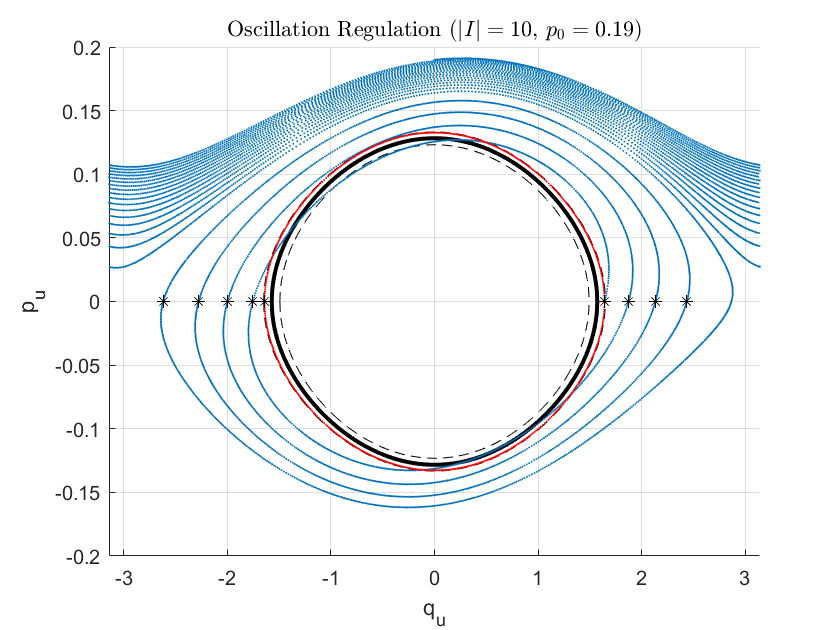

if sims.osc_reg.RUN
for i = 1:size(sims.osc_reg.qp0s,1)
% Initial condition for injection
qp0 = sims.osc_reg.qp0s(:,i)';

% Set simulation time
Treg = T;

% Set title of this initial condition
if qp0(2) == 0
    titlestr = sprintf(...
    'Oscillation Regulation ($|I| = %d$, $q_0 = \\pi/%d$)',...
    Iin, round(pi/qp0(1)));
elseif qp0(1) == 0
    titlestr = sprintf(...
    'Oscillation Regulation ($|I| = %d$, $p_0 = %.2f$)',...
    abs(Idiss), qp0(2));
end % if qp0

% Update the dynamics for this iteration
fxinreg = @(t,x)qpdf(wrapToPi(x(1)),x(2),Iin);
fxdissreg = @(t,x)qpdf(wrapToPi(x(1)),x(2),Idiss);
fxzeroreg = @(t,x)fxconst(t,x,0);

% Set the desired oscillation location and hysteresis
qdes = pi/2;
delta = 0.05;
 
% Set the regulation event to trigger whenever pu = 0
getP = @(q,p) p;
pZeroEvent = @(t,qp) regulationEvent(t,qp,getP,0,0);
regOptions = odeset(baseInOptions,'Events',pZeroEvent);

% Keep track of the VNHC to use, where
% 1 = injection, 0 = constant, -1 = dissipation
supervisor = (i == 1) - (i == 2);
% Store the qa  values
qac = 0; % current qa
qas = []; % all qa values over time
% Keep track of the solution
soln.x = [];
soln.y = [];
soln.xe = [];
soln.ye = [];
soln.ie = [];
% Run for T seconds
t = 0; % initial time condition
x0 = qp0; % initial phase condition
keepRunning = true; 
while keepRunning
    % Simulate the VNHC until we need to toggle
    if supervisor == 1
        % Inject until we hit the qu axis
        sol = ode45(fxinreg,[t,Treg],x0,regOptions);
        % We stopped, now track qa
        qas = [qas, qaf(Iin,sol.y(2,:))];
    elseif supervisor == -1
        % Dissipate until we hit the qu axis
        sol = ode45(fxdissreg,[t,Treg],x0,regOptions);
        % We stopped, now track qa
        qas = [qas, qaf(Idiss,sol.y(2,:))];
    else % supervisor == 0
        % Keep qa the same until we hit the qu axis again
        sol = ode45(fxzeroreg,[t,Treg],x0,regOptions);
         % Update the qa value
        qas = [qas, 0.*ones(size(sol.x))];
    end % if supervisor
    % Wrap the qu values
    sol.y(1,:) = wrapToPi(sol.y(1,:));
    % Keep track of these solutions by concatenating
    soln.x = [soln.x, sol.x];
    soln.y = [soln.y, sol.y];
    soln.xe = [soln.xe, sol.xe];
    soln.ye = [soln.ye, sol.ye];
    soln.ie = [soln.ie, sol.ie];
    % Update the initial condition for the next iteration
    x0 = sol.y(:,end);
    % Update the initial time state for the next iteration
    t = sol.x(end);
    % If the simulation went up to time T, then we're done.
    if t >= Treg
        keepRunning = false;
    else % otherwise, update the supervisor
        if abs(x0(1)) < (1-delta)*qdes
            % inject because we're below oscillation
            supervisor = 1;
        elseif abs(x0(1)) > (1+delta)*qdes
            % Dissipate because we're above it
            supervisor = -1;
        else
            % Keep qa constant because we're in range
            supervisor = 0;
        end % if x0(1)
    end % if t > T
end % while keepRunning

%%% Plot the orbits
% First, we know that E(pi,0)/2 gives us the term in
% front of (1-cos(qu))
Epib2 = Enomf(pi,0)/2;
% Get the level set of the energy of our desired oscillation
Edes = Enomf(qdes,0);
Edesmd = Enomf((1-delta)*qdes,0);
Edespd = Enomf((1+delta)*qdes,0);
% Since Edes = E(pi,0)/2 (1-cos(qu)), we get that the
% maximal qu is at acos(1 - Edes/(E(pi,0)/2))
mu0 = acos(1 - Edes/Epib2); % maximal q (should be qdes)
mu0md = acos(1 - Edesmd/Epib2); % max q for (1-d)qdes
mu0pd = acos(1 - Edespd/Epib2); % max q for (1+d)qdes
% Then we compute the value of E(0,1) to get the
% term in front of pu^2
E01 = Enomf(0,1);
% Finally, we have E(pi,0)/2*(1-cos(qu)) + E(0,1)pu^2 == Edes,
% which means that
% pu^2 = (Edes - E(pi,0)/2*(1-cos(qu))/E01
qs = linspace(-mu0,mu0,1000);
ps = sqrt((Edes - Epib2.*(1-cos(qs)))/E01);
qsmd = linspace(-mu0md,mu0md,1000);
psmd = sqrt((Edesmd - Epib2.*(1-cos(qsmd)))/E01);
qspd = linspace(-mu0pd,mu0pd,1000);
pspd = sqrt((Edespd - Epib2.*(1-cos(qspd)))/E01);

% Plot the orbits
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k','LineWidth',2); % level set E0
plot(qsmd,psmd,'k--',qsmd,-psmd,'k--'); % level set (1-delta)E0
plot(qspd,pspd,'k--',qspd,-pspd,'k--'); % level set (1+delta)E0
% Find the time when qa remains zero
tqa0 = find(qas,1,'last');
% Now plot the injection orbit, with scatter point size 0.5 and a 
% light blue colour so it looks nice, along with the qa
% constant orbit in red
scatter(soln.y(1,1:tqa0),soln.y(2,1:tqa0),...
        0.5,[0,0.447,0.7410]);
scatter(soln.y(1,tqa0:end),soln.y(2,tqa0:end),...
        0.5,'red');
% Show every time we hit the qu axis in black
scatter(soln.ye(1,:),soln.ye(2,:),'k*');
% Give it axis labels
xlabel('q_u');
ylabel('p_u');
title(titlestr,'Interpreter','latex');
xlim([-pi,pi]);
ylim([-0.2,0.2]);
grid on;
hold off;
if sims.osc_reg.SAVE
savetitle = sprintf('images/acrobot_osc_orbit_%d',i);
saveas(orbitFig,savetitle,'png');
saveas(orbitFig,savetitle,'fig');
end % SAVE
end % for i
end % RUN

## Part 4: Rotation Regulation

We regulate rotations and use a simple supervisor

if sims.rot_reg.RUN
for i = 1:size(sims.rot_reg.qp0s,1)
% Initial condition for injection
qp0 = sims.rot_reg.qp0s(i,:)';

% Set simulation time
Treg = T;

% Set title of this initial condition
if qp0(2) == 0
    titlestr = sprintf(...
    'Rotation Regulation ($|I| = %d$, $q_0 = \\pi/%d$)',...
    abs(Iin), round(pi/qp0(1)));
elseif qp0(1) == 0
    titlestr = sprintf(...
    'Rotation Regulation ($|I| = %d$, $p_0 = %.2f$)',...
    abs(Idiss), qp0(2));
end % if qp0

% Update the dynamics for this iteration
fxinreg = @(t,x)qpdf(wrapToPi(x(1)),x(2),Iin);
fxdissreg = @(t,x)qpdf(wrapToPi(x(1)),x(2),Idiss);
fxzeroreg = @(t,x)fxconst(t,x,0);

% Set the desired oscillation location and hysteresis
pdes = 0.19;
delta = 0.02;
 
% Set the regulation event to trigger whenever qu = 0
getQ = @(q,p) wrapToPi(q);
qZeroEvent = @(t,qp) regulationEvent(t,qp,getQ,0,0);
regOptions = odeset(baseInOptions,'Events',qZeroEvent);

% Keep track of the VNHC to use, where
% 1 = injection, 0 = constant, -1 = dissipation
supervisor = (i == 1) - (i == 2);
% Store the qa  values
qac = 0; % current qa
qas = []; % all qa values over time
% Keep track of the solution
soln.x = [];
soln.y = [];
soln.xe = [];
soln.ye = [];
soln.ie = [];
% Run for T seconds
t = 0; % initial time condition
x0 = qp0; % initial phase condition
keepRunning = true; 
while keepRunning
    % Simulate the VNHC until we need to toggle
    if supervisor == 1
        % Inject until we hit the qu axis
        sol = ode45(fxinreg,[t,Treg],x0,regOptions);
        % We stopped, now track qa
        qas = [qas, qaf(Iin,sol.y(2,:))];
    elseif supervisor == -1
        % Dissipate until we hit the qu axis
        sol = ode45(fxdissreg,[t,Treg],x0,regOptions);
        % We stopped, now track qa
        qas = [qas, qaf(Idiss,sol.y(2,:))];
    else % supervisor == 0
        % Keep qa the same until we hit the qu axis again
        sol = ode45(fxzeroreg,[t,Treg],x0,regOptions);
         % Update the qa value
        qas = [qas, 0.*ones(size(sol.x))];
    end % if supervisor
    % Wrap the qu values
    sol.y(1,:) = wrapToPi(sol.y(1,:));
    % Keep track of these solutions by concatenating
    soln.x = [soln.x, sol.x];
    soln.y = [soln.y, sol.y];
    % Update the initial condition for the next iteration
    x0 = sol.y(:,end);
    % For some reason this system tracks when q = pi as well
    % as when q = 0, so we ignore the ones where q = pi
    if size(sol.ye,1) > 0 && abs(pi-abs(x0(1))) > 1
        soln.xe = [soln.xe, sol.xe];
        soln.ye = [soln.ye, sol.ye];
        soln.ie = [soln.ie, sol.ie];
    end
    % Update the initial time state for the next iteration
    t = sol.x(end);
    % If the simulation went up to time T, then we're done.
    if t >= Treg
        keepRunning = false;
    else % otherwise, update the supervisor
        % Don't change the supervisor if we hit qu = pi
        if abs(pi - abs(x0(1))) < 1
            continue;
        end
        if abs(x0(2)) < (1-delta)*pdes
            % inject because we're below rotation
            supervisor = 1;
        elseif abs(x0(2)) > (1+delta)*pdes
            % Dissipate because we're above it
            supervisor = -1;
        else
            % Keep qa constant because we're in range
            supervisor = 0;
        end % if x0(2)
    end % if t > T
end % while keepRunning

%%% Plot the orbits
% First, we know that E(pi,0)/2 gives us the term in
% front of (1-cos(qu))
Epib2 = Enomf(pi,0)/2;
% Get the level set of the energy of our desired oscillation
Edes = Enomf(0,pdes);
Edesmd = Enomf(0,(1-delta)*pdes);
Edespd = Enomf(0,(1+delta)*pdes);
% Then we compute the value of E(0,1) to get the
% term in front of pu^2
E01 = Enomf(0,1);
% Finally, we have E(pi,0)/2*(1-cos(qu)) + E(0,1)pu^2 == Edes,
% which means that
% pu^2 = (Edes - E(pi,0)/2*(1-cos(qu))/E01
qs = linspace(-pi,pi,1000);
ps = sqrt((Edes - Epib2.*(1-cos(qs)))/E01);
psmd = sqrt((Edesmd - Epib2.*(1-cos(qs)))/E01);
pspd = sqrt((Edespd - Epib2.*(1-cos(qs)))/E01);

% Plot the orbits
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k','LineWidth',2); % level set E0
plot(qs,psmd,'k--',qs,-psmd,'k--') % level set (1-delta)E0
plot(qs,pspd,'k--',qs,-pspd,'k--') % level set (1+delta)E0
% Find the time when qa remains zero
tqa0 = find(qas,1,'last');
% Now plot the injection orbit, with scatter point size 0.5 and a 
% light blue colour so it looks nice, along with the qa
% constant orbit in red
scatter(soln.y(1,1:tqa0),soln.y(2,1:tqa0),...
        0.5,[0,0.447,0.7410]);
scatter(soln.y(1,tqa0:end),soln.y(2,tqa0:end),...
        0.5,'red');
% Show every time we hit the pu axis in black
scatter(soln.ye(1,:),soln.ye(2,:),'k*');
% Give it axis labels
xlabel('q_u');
ylabel('p_u');
title(titlestr,'Interpreter','latex');
xlim([-pi,pi]);
ylim([-0.25,0.25]);
% Zoom in on rotations for dissipation
if qp0(2) ~= 0
    ylim([0,0.25]);
end
grid on;
hold off;
if sims.rot_reg.SAVE
savetitle = sprintf('images/acrobot_rot_orbit_%d',i);
saveas(orbitFig,savetitle,'png');
saveas(orbitFig,savetitle,'fig');
end % SAVE
end % for i
end % RUN

## Part 4: Energy Regulation

We regulate energy using a simple supervisor which toggles between injection and dissipation VNHCs.

Given an energy $E_0$ and hysteresis $\delta \in [0,1]$, we use the injection VNHC if $E < (1-\delta)E_0$, the dissipation VNHC if $E > (1+\delta)E_0$. We only toggle when we hit one of these boundaries, otherwise $q_a$ stays constant at whatever the previous value was on the boundary.

### a) Energy Regulation for Oscillations

We stabilize an oscillation with $E_0 = E(\pi/2,0)$ starting at $(q_u,p_u) = (\pi/4,0)$ (we could start smaller but it takes much longer because injection is slow). Here, $\delta = 5\%$.

Note that we need to use a much smaller $I$, so that the approximation with the nominal pendulum works well. If $I$ is too large, we cannot stabilize an oscillation

if sims.energy_reg.RUN
for i = 1:1 % Run this test for different I values
% Make the dynamics use a smaller I so we get better results
if i == 1
    % Set the control value
    Iinreg = Iin;
    Idissreg = Idiss;
    % Set the time
    Treg = 30;
    % Set the initial condition for the simulation
    % Interestingly, if you start at qu = (pi/4) it works...??
    %qp0 = [pi/32;0];
    qp0 = [pi/32;0];
    % TODO: Set the filename for the image
elseif i == 2
    % Set the control value
    Iinreg = Iin;
    Idissreg = Idiss;
    % Set the time
    Treg = 30;
    % Set the initial condition for the simulation
    qp0 = [0.5;0];
    % TODO: Set the filename for the image
else
    % Set the control value
    Iinreg = 1;
    Idissreg = -1;
    % Increase the time because I is small
    Treg = 0;
    % Set the initial condition for the simulation
    qp0 = [pi/8;0];
    % TODO: Set the filename for the image
end
% Update the dynamics for this iteration
fxinreg = @(t,x)qpdf(wrapToPi(x(1)),x(2),Iinreg);
fxdissreg = @(t,x)qpdf(wrapToPi(x(1)),x(2),Idissreg);

% Set the desired oscillation energy and hysteresis
E0 = Enomf(pi/2,0);
delta = 0.05;
% Set the regulation events
% increasing through E0-delta
regInIEvent = @(t,qp)regulationEvent(t,qp,Enomf,(1-delta)*E0,1);
regInIOptions = odeset(baseInOptions,'Events',regInIEvent);
% Decreasing through E0-delta
regInDEvent = @(t,qp)regulationEvent(t,qp,Enomf,(1-delta)*E0,-1);
regInDOptions = odeset(baseInOptions,'Events',regInDEvent);
% Increasing through E0+delta
regDissIEvent = @(t,qp)regulationEvent(t,qp,Enomf,(1+delta)*E0,1);
regDissIOptions = odeset(baseInOptions,'Events',regDissIEvent);
% Decreasing through E0+delta
regDissDEvent = @(t,qp)regulationEvent(t,qp,Enomf,(1+delta)*E0,-1);
regDissDOptions = odeset(baseInOptions,'Events',regDissDEvent);

% Keep track of the VNHC to use, where
% 1 = injection, 0 = constant, -1 = dissipation
supervisor = 1;
% Store the qa  values
qac = 0;
qas = [];
% Keep track of the solution
soln.x = [];
soln.y = [];
soln.xe = [];
soln.ye = [];
soln.ie = [];
% Run for T seconds
t = 0; % initial time condition
x0 = qp0; % initial phase condition
keepRunning = true; 
while keepRunning
    % Simulate the VNHC until we need to toggle
    if supervisor == 1
        % Inject until we go above E0-delta
        sol = ode45(fxinreg,[t,Treg],x0,regInIOptions);
        % We stopped, now set the constant for qa
        qac = double(subs(qaa,[I,pu],[Iinreg,sol.y(2,end)]));
        qas = [qas, qaf(Iinreg,sol.y(2,:))];
        % Update the supervisor
        supervisor = 0;
    elseif supervisor == -1
        % dissipation until we go below E0 + delta
        sol = ode45(fxdissreg,[t,Treg],x0,regDissDOptions);
        % We stopped, now set the constant for qa
        qac = double(subs(qaa,[I,pu],[Idissreg,sol.y(2,end)]));
        qas = [qas, qaf(Idissreg,sol.y(2,:))];
        % Update the supervisor
        supervisor = 0;
    else % supervisor == 0
        % constant qa until we go outside hysteresis
        % First, we set the dynamics
        fxc = @(t,x)fxconst(t,x,qac);
        % Now do two simulations, one for each boundary of
        % hysteresis values where we go below E0 - delta
        % or above E0 + delta
        sol1 = ode45(fxc,[t,Treg],x0,regInDOptions); % E0 - delta
        sol2 = ode45(fxc,[t,Treg],x0,regDissIOptions); % E0+delta
        % Find which one of the two occurs first, if any
        if size(sol1.xe,1) > 0 && size(sol2.xe,1) > 0
            % Both solutions occured, take the one which had
            % the minimum crossover time
            if sol1.xe < sol2.xe
                % Went below E0 - delta first, inject
                sol = sol1;
                supervisor = 1;
            else % Went above E0 + delta first, dissipate
                sol = sol2;
                supervisor = -1;
            end
        elseif size(sol1.xe,1) ~= 0 && size(sol2.xe,1) == 0
            % We only went below E0 - delta, inject
            sol = sol1;
            supervisor = 1;
        elseif size(sol1.xe,1) == 0 && size(sol2.xe,1) ~= 0
            % We only went above E0 + delta, dissipate
            sol = sol2;
            supervisor = -1;
        else % both xe are empty
            % We did not go through either, so we stayed in
            % the range. Both solutions are the same
            % so we pick sol1.
            sol = sol1;
        end
        % Update the qa value
        qas = [qas, qac.*ones(size(sol.x))];
    end
    % Keep track of these solutions by concatenating
    soln.x = [soln.x, sol.x];
    soln.y = [soln.y, sol.y];
    soln.xe = [soln.xe, sol.xe];
    soln.ye = [soln.ye, sol.ye];
    soln.ie = [soln.ie, sol.ie];
    % Update the initial condition for the next iteration
    x0 = sol.y(:,end);
    % Update the initial time state for the next iteration
    t = sol.x(end);
    % If the simulation went up to time T, then we're done.
    if t >= Treg
        keepRunning = false;
    end
end % while

%%% Plot the orbits
% First, we know that E(pi,0)/2 gives us the term in
% front of (1-cos(qu))
Epib2 = Enomf(pi,0)/2;
% Since E0 = E(pi,0)/2 (1-cos(qu)), we get that the
% maximal qu is at acos(1 - E0/(E(pi,0)/2))
mu0 = acos(1 - E0/Epib2); % maximal q for E0
mu0md = acos(1 - (1-delta)*E0/Epib2); % max q for (1-d)E0
mu0pd = acos(1 - (1+delta)*E0/Epib2); % max q for (1+d)E0
% Then we compute the value of E(0,1) to get the
% term in front of pu^2
E01 = Enomf(0,1);
% Finally, we have E(pi,0)/2(1-cos(qu)) + E(0,1)pu^2 == E0,
% which means that
% pu^2 = (E0 - E(pi,0)/2*(1-cos(qu))/E01
qs = linspace(-mu0,mu0,1000);
ps = sqrt((E0 - Epib2.*(1-cos(qs)))/E01);
qsmd = linspace(-mu0md,mu0md,1000);
psmd = sqrt(((1-delta)*E0 - Epib2.*(1-cos(qsmd)))/E01);
qspd = linspace(-mu0pd,mu0pd,1000);
pspd = sqrt(((1+delta)*E0 - Epib2.*(1-cos(qspd)))/E01);

% Plot the orbits
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k'); % level set E0
plot(qsmd,psmd,'k--',qsmd,-psmd,'k--') % level set (1-delta)E0
plot(qspd,pspd,'k--',qspd,-pspd,'k--') % level set (1+delta)E0
% Now plot the orbit itself
plot(soln.y(1,:),soln.y(2,:));
xlabel('qu');
ylabel('pu');
title(sprintf(...
    'Oscillation Regulation ($I = %d$, $q_0 = \\pi/%d$)',...
    Iinreg, round(pi/qp0(1))),...
    'Interpreter','latex');
hold off;
end % for
end